# Beam-pattern pipeline -- WHOLE SESSION (batch over every trial)

Batch sibling of beam_pipeline_one_trial.m. Runs the SAME end-to-end flow stage 1 bp_proc_vicon -> stage 2+3 run_beamaim_maze -> QC plots -> stage 4 for EVERY trial in one session (one batID + one date), instead of one trial.

2026-07-22: stage 4 (trial analysis) and the pooled pre-flight figure are now COMMENTED OUT here -- trial-level analysis moved to trial_analysis_batch_processing.m (reads the bp_proc files this script produces; writes one output set PER TRIAL into Z:\Rie\Data\Beampattern_proc\<batID>\trial_analysis\<date>\). To re-enable the old in-line stage 4, un-comment the two %{ ... %} blocks below.

TRIAL DISCOVERY (hands-off "whole session"): Scans the position pipeline's Bat_Position folder for this session's bat_pos files ([batID](http://batid)_<date>_<NN>_bat_pos.mat) and processes each. A trial's position (bat_pos) must be done first -- which the beam analysis needs anyway -- so those files are the natural per-session trial list. To restrict/reorder, set trials_override = [3 4 5] (trial numbers) below.

Each trial is wrapped in try/catch; a per-trial + pooled summary prints at end. Re-running a trial replaces its stage-4 rows (keyed on bat/session/trial), so re-running the session is safe.

Written 2026-07-18 as the batch sibling of beam_pattern_pipeline_trial.m.

## 0. Paths (once per MATLAB session)

setup_paths

Beam-pattern pipeline paths added (Z:\Rie\Analysis\Beampattern_analysis).


## ============================ CONFIG (EDIT ME) ============================

batID     = 'batA125';
date_data = '20260708';

% -- which stages to run per trial --
do_stage1  = true;   % stage 1  bp_proc_vicon (per-mic distance-compensated levels)
do_stage23 = true;   % stage 2+3 run_beamaim_maze (line-of-sight mic selection)
% do_stage4  = true;   % stage 4 -> trial_analysis_batch_processing.m
make_plots = true;   % per-trial QC plots (saved to disk, then figures closed)

% -- position-pipeline inputs (where position_processing writes) --
bat_pos_dir = 'Z:\Rie\Analysis\position_processing\Bat_Position';
mic_pos_dir = 'Z:\Rie\Analysis\position_processing\Mic_positions';

% -- raw Avisoft inputs: EDIT these roots + patterns to match your data tree.
%    (defaults follow beam_pipeline_one_trial.m's example paths -- confirm them.)
combined_dir = 'Z:\Rie\Data\Raw_Data\<batID>\<date>\Mic_data\Combined_trial_data';
combined_pat = 'T%T7%_combined.mat';           % e.g. T0000003_combined.mat
detected_dir = 'Z:\Rie\Data\Preprocessing\Mic\Mic_Data_Detected\<batID>\done';
detected_pat = '%D%_T%T7%_detected.mat';       % e.g. 20260709_T0000003_detected.mat

% -- output roots (defaults match the single-trial scripts) --
out_root_proc  = 'Z:\Rie\Data\Beampattern_proc';        % stage-1 bp_proc .mat + plots (per bat)
% out_root_stats = 'Z:\Rie\Stats\Beampattern_analysis'; % stage-4 output (MOVED OUT)

% -- optional explicit trial list (overrides auto-scan). [] = auto-scan bat_pos --
trials_override = [];

## =========================================================================

% Resolve <batID>/<date> tokens in the raw-data folder roots.
combined_dir = strrep(strrep(combined_dir, '<batID>', batID), '<date>', date_data);
detected_dir = strrep(strrep(detected_dir, '<batID>', batID), '<date>', date_data);

mic_pos_file = fullfile(mic_pos_dir, sprintf('mic_pos_%s.mat', date_data));
if ~isfile(mic_pos_file)
    error('Session mic_pos file not found: %s (run position_processing first).', mic_pos_file);
end

% ---- build the trial list ----
if ~isempty(trials_override)
    trial_nums = trials_override(:).';
    bat_pos_files = arrayfun(@(n) fullfile(bat_pos_dir, ...
        sprintf('%s_%s_%02d_bat_pos.mat', batID, date_data, n)), trial_nums, 'UniformOutput', false);
else
    d = dir(fullfile(bat_pos_dir, sprintf('%s_%s_*_bat_pos.mat', batID, date_data)));
    trial_nums = []; bat_pos_files = {};
    for i = 1:numel(d)
        tok = regexp(d(i).name, sprintf('%s_%s_(\\d+)_bat_pos', batID, date_data), 'tokens', 'once');
        if ~isempty(tok)
            trial_nums(end+1)    = str2double(tok{1});                  %#ok<SAGROW>
            bat_pos_files{end+1} = fullfile(d(i).folder, d(i).name);    %#ok<SAGROW>
        end
    end
    [trial_nums, si] = sort(trial_nums);
    bat_pos_files    = bat_pos_files(si);
end
if isempty(trial_nums)
    error('No bat_pos files found for %s %s in %s', batID, date_data, bat_pos_dir);
end
fprintf('\n==== Beam session batch: %s %s -- %d trial(s) ====\n', batID, date_data, numel(trial_nums));


==== Beam session batch: batA125 20260708 -- 18 trial(s) ====



n_ok = 0; n_fail = 0; n_skip = 0;
failed = {}; skipped = {};
for i = 1:numel(trial_nums)
    n = trial_nums(i);
    bat_pos_file  = bat_pos_files{i};
    combined_file = fullfile(combined_dir, ...
        strrep(strrep(strrep(combined_pat,'%D%',date_data),'%T7%',sprintf('%07d',n)),'%N%',sprintf('%d',n)));
    detected_file = fullfile(detected_dir, ...
        strrep(strrep(strrep(detected_pat,'%D%',date_data),'%T7%',sprintf('%07d',n)),'%N%',sprintf('%d',n)));
    fprintf('\n---- [%d/%d] trial %02d ----\n', i, numel(trial_nums), n);

    if do_stage1 && (~isfile(combined_file) || ~isfile(detected_file))
        if ~isfile(combined_file), fprintf(2, '  missing combined_file: %s\n', combined_file); end
        if ~isfile(detected_file), fprintf(2, '  missing detected_file: %s\n', detected_file); end
        fprintf('  -> skipping trial %02d\n', n);
        skipped{end+1} = sprintf('%02d', n); n_skip = n_skip + 1; %#ok<SAGROW>
        continue;
    end

    try


---- [1/18] trial 02 ----


  missing combined_file: Z:\Rie\Data\Raw_Data\batA125\20260708\Mic_data\Combined_trial_data\T0000002_combined.mat


  missing detected_file: Z:\Rie\Data\Preprocessing\Mic\Mic_Data_Detected\batA125\done\20260708_T0000002_detected.mat


  -> skipping trial 02



---- [2/18] trial 03 ----


  missing combined_file: Z:\Rie\Data\Raw_Data\batA125\20260708\Mic_data\Combined_trial_data\T0000003_combined.mat


  missing detected_file: Z:\Rie\Data\Preprocessing\Mic\Mic_Data_Detected\batA125\done\20260708_T0000003_detected.mat


  -> skipping trial 03



---- [3/18] trial 04 ----


  missing detected_file: Z:\Rie\Data\Preprocessing\Mic\Mic_Data_Detected\batA125\done\20260708_T0000004_detected.mat


  -> skipping trial 04



---- [4/18] trial 08 ----



---- [5/18] trial 09 ----



---- [6/18] trial 10 ----



---- [7/18] trial 11 ----



---- [8/18] trial 12 ----



---- [9/18] trial 13 ----



---- [10/18] trial 14 ----



---- [11/18] trial 15 ----



---- [12/18] trial 16 ----



---- [13/18] trial 17 ----



---- [14/18] trial 18 ----



---- [15/18] trial 19 ----



---- [16/18] trial 20 ----



---- [17/18] trial 21 ----



---- [18/18] trial 22 ----


## stage 1 -- bp_proc

        if do_stage1
            cfg = struct();
            cfg.combined_file = combined_file;
            cfg.detected_file = detected_file;
            cfg.bat_pos_file  = bat_pos_file;
            cfg.mic_pos_file  = mic_pos_file;
            cfg.tempC = []; cfg.humid = [];
            cfg.pos_units = 'mm'; cfg.axis_orient = [1 2 3]; cfg.head_normal = [0 0 1];
            cfg.mic_sens_file = ''; cfg.mic_bp_file = ''; cfg.mic_sens_dB = 0;
            cfg.out_dir = ''; cfg.out_name = '';
            cfg.out_root = out_root_proc;
            cfg.bat_id   = batID;
            data = bp_proc_vicon(cfg);
            bp_proc_file = data.saved_file;
        else
            % locate an existing bp_proc file for this trial (exact 7-digit match)
            bpdir = fullfile(out_root_proc, batID, 'beampattern_output');
            ex = dir(fullfile(bpdir, sprintf('%s_T%07d_mic_data_bp_proc.mat', date_data, n)));
            if isempty(ex)
                error('no existing bp_proc file for trial %02d in %s (set do_stage1=true)', n, bpdir);
            end
            bp_proc_file = fullfile(ex(1).folder, ex(1).name);
        end
        fprintf('  bp_proc_file = %s\n', bp_proc_file);

Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.5 1553.5] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000008_mic_data_bp_proc.mat (45 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000008_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Call duration marking is problematic in Call #163  [marked start is 1454 pt(s) BEFORE the extraction window]
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.4 1553.4] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000009_mic_data_bp_proc.mat (66 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000009_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.7 1553.5] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000010_mic_data_bp_proc.mat (23 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000010_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Call duration marking is problematic in Call #130  [marked start is 292 pt(s) BEFORE the extraction window]
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.4 1553.7] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000011_mic_data_bp_proc.mat (35 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000011_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Call duration marking is problematic in Call #172  [marked start is 280 pt(s) BEFORE the extraction window]
Call duration marking is problematic in Call #173  [marked start is 295 pt(s) BEFORE the extraction window]
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.6 1553.3] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000012_mic_data_bp_proc.mat (35 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000012_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.7 1553.1] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000013_mic_data_bp_proc.mat (28 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000013_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.6 1553.0] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000014_mic_data_bp_proc.mat (28 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000014_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.5 1553.3] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000015_mic_data_bp_proc.mat (50 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000015_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.5 1553.1] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000016_mic_data_bp_proc.mat (32 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000016_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Call duration marking is problematic in Call #178  [marked start is 2043 pt(s) BEFORE the extraction window]
Call duration marking is problematic in Call #243  [marked end is 1255 pt(s) AFTER the extraction window (win=2500 pt)]
Call duration marking is problematic in Call #246  [marked end is 1876 pt(s) AFTER the extraction window (win=2500 pt)]
Call duration marking is problematic in Call #250  [marked end is 876 pt(s) AFTER the extraction window (win=2500 pt)]
Call duration marking is problematic in Call #251  [marked end is 1098 pt(s) AFTER the extraction window (win=2500 pt)]
Call duration marking is problematic in Call #254  [

  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000017_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Call duration marking is problematic in Call #158  [marked end is 15 pt(s) AFTER the extraction window (win=2500 pt)]
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.4 1553.3] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000018_mic_data_bp_proc.mat (62 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000018_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.5 1553.3] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000019_mic_data_bp_proc.mat (41 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000019_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.5 1553.2] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000020_mic_data_bp_proc.mat (29 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000020_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Call duration marking is problematic in Call #86  [marked start is 25 pt(s) BEFORE the extraction window]
Call duration marking is problematic in Call #87  [marked start is 11 pt(s) BEFORE the extraction window]
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.4 1553.6] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000021_mic_data_bp_proc.mat (65 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000021_mic_data_bp_proc.mat


Using T = 22.0 C, H = 44 %
Trimming Vicon track 4026 -> 4000 frames (16.00 s) to match Avisoft.
Channel/mic map: channel(s) [8  13] (Mic_[8  13]) have no position in mic_pos -- set to NaN so the other mics keep their true positions. Label/solve that mic in the landmark file if it should exist.
Channel/mic map: 24 channel(s); 22 located, 2 NaN (missing mic).
Call duration marking is problematic in Call #141  [marked end is 1039 pt(s) AFTER the extraction window (win=2500 pt)]
Added take-off-centred coords (data.takeoff_centered): pivot [-1012.3 1553.7] mm -> (0,0); deeper-in-maze = +Y.
Saved Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000022_mic_data_bp_proc.mat (48 calls with track)


  bp_proc_file = Z:\Rie\Data\Beampattern_proc\batA125\beampattern_output\20260708_T0000022_mic_data_bp_proc.mat


## stage 2+3 -- beam-aim per call

        out = [];
        if do_stage23
            out = run_beamaim_maze(struct( ...
                'bp_proc_file', bp_proc_file, ...
                'bat_pos_file', bat_pos_file, ...
                'mic_select',   'lineofsight'));
        end

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 1.840499. Normalizing...

Data is not normalized! The pdf sums to: 1.974812. Normalizing...

Data is not normalized! The pdf sums to: 2.434993. Normalizing...

Data is not normalized! The pdf sums to: 2.278487. Normalizing...

Data is not normalized! The pdf sums to: 2.037997. Normalizing...

Data is not normalized! The pdf sums to: 1.844789. Normalizing...

Data is not normalized! The pdf sums to: 4.695191. Normalizing...

Data is not normalized! The pdf sums to: 2.285139. Normalizing...

Data is not normalized! The pdf sums to: 2.464375. Normalizing...

Data is not normalized! The pdf sums to: 3.525113. Normalizing...

Data is not normalized! The pdf sums to: 1.865895. Normalizing...

Data is not normalized! The pdf sums to: 2.789812. Normalizing...

Data is not normalized! The pdf sums to: 3.146820. Normalizing...

Data is not normalized! The pdf sums to: 4.912648. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 1.758541. Normalizing...

Data is not normalized! The pdf sums to: 2.269199. Normalizing...

Data is not normalized! The pdf sums to: 1.957469. Normalizing...

Data is not normalized! The pdf sums to: 2.003733. Normalizing...

Data is not normalized! The pdf sums to: 9.517650. Normalizing...

Data is not normalized! The pdf sums to: 4.176133. Normalizing...

Data is not normalized! The pdf sums to: 1.547171. Normalizing...

Data is not normalized! The pdf sums to: 2.628382. Normalizing...

Data is not normalized! The pdf sums to: 2.584497. Normalizing...

Data is not normalized! The pdf sums to: 1.624631. Normalizing...

Data is not normalized! The pdf sums to: 1.666198. Normalizing...

Data is not normalized! The pdf sums to: 2.822730. Normalizing...

Data is not normalized! The pdf sums to: 2.141538. Normalizing...

Data is not normalized! The pdf sums to: 3.074635. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 7.617332. Normalizing...

Data is not normalized! The pdf sums to: 0.475168. Normalizing...

Data is not normalized! The pdf sums to: 0.275453. Normalizing...

Data is not normalized! The pdf sums to: 4.341337. Normalizing...

Data is not normalized! The pdf sums to: 5.469503. Normalizing...

Data is not normalized! The pdf sums to: 1.605585. Normalizing...

Data is not normalized! The pdf sums to: 4.225343. Normalizing...

Data is not normalized! The pdf sums to: 0.293308. Normalizing...

Data is not normalized! The pdf sums to: 1.916106. Normalizing...

Data is not normalized! The pdf sums to: 1.686374. Normalizing...

Data is not normalized! The pdf sums to: 1.934582. Normalizing...

Data is not normalized! The pdf sums to: 2.652062. Normalizing...

Data is not normalized! The pdf sums to: 4.459239. Normalizing...

Saved beam-aim (23 calls) back to Z:\Rie\Data\Beampattern_proc\batA125\beampatter

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 2.058671. Normalizing...

Data is not normalized! The pdf sums to: 3.204825. Normalizing...

Data is not normalized! The pdf sums to: 2.742260. Normalizing...

Data is not normalized! The pdf sums to: 2.569210. Normalizing...

Data is not normalized! The pdf sums to: 2.179932. Normalizing...

Data is not normalized! The pdf sums to: 2.088908. Normalizing...

Data is not normalized! The pdf sums to: 1.937788. Normalizing...

Data is not normalized! The pdf sums to: 2.408836. Normalizing...

Data is not normalized! The pdf sums to: 0.465963. Normalizing...

Data is not normalized! The pdf sums to: 3.571650. Normalizing...

Data is not normalized! The pdf sums to: 6.617166. Normalizing...

Data is not normalized! The pdf sums to: 6.678499. Normalizing...

Data is not normalized! The pdf sums to: 1.838424. Normalizing...

Data is not normalized! The pdf sums to: 4.099906. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 2.007964. Normalizing...

Data is not normalized! The pdf sums to: 4.195636. Normalizing...

Data is not normalized! The pdf sums to: 2.969641. Normalizing...

Data is not normalized! The pdf sums to: 1.969048. Normalizing...

Data is not normalized! The pdf sums to: 2.636400. Normalizing...

Data is not normalized! The pdf sums to: 2.746502. Normalizing...

Data is not normalized! The pdf sums to: 2.112872. Normalizing...

Data is not normalized! The pdf sums to: 5.597581. Normalizing...

Data is not normalized! The pdf sums to: 7.349659. Normalizing...

Data is not normalized! The pdf sums to: 6.431335. Normalizing...

Data is not normalized! The pdf sums to: 3.165029. Normalizing...

Data is not normalized! The pdf sums to: 2.310101. Normalizing...

Data is not normalized! The pdf sums to: 0.265208. Normalizing...

Data is not normalized! The pdf sums to: 0.453625. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 2.590072. Normalizing...

Data is not normalized! The pdf sums to: 3.180136. Normalizing...

Data is not normalized! The pdf sums to: 2.046323. Normalizing...

Data is not normalized! The pdf sums to: 1.689438. Normalizing...

Data is not normalized! The pdf sums to: 1.501010. Normalizing...

Data is not normalized! The pdf sums to: 3.596039. Normalizing...

Data is not normalized! The pdf sums to: 8.257366. Normalizing...

Data is not normalized! The pdf sums to: 3.883589. Normalizing...

Data is not normalized! The pdf sums to: 1.624368. Normalizing...

Data is not normalized! The pdf sums to: 0.335721. Normalizing...

Data is not normalized! The pdf sums to: 2.575630. Normalizing...

Data is not normalized! The pdf sums to: 1.980182. Normalizing...

Data is not normalized! The pdf sums to: 2.048951. Normalizing...

Data is not normalized! The pdf sums to: 1.570871. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 2.552095. Normalizing...

Data is not normalized! The pdf sums to: 3.730496. Normalizing...

Data is not normalized! The pdf sums to: 2.528004. Normalizing...

Data is not normalized! The pdf sums to: 2.319784. Normalizing...

Data is not normalized! The pdf sums to: 4.259086. Normalizing...

Data is not normalized! The pdf sums to: 2.582253. Normalizing...

Data is not normalized! The pdf sums to: 3.530936. Normalizing...

Data is not normalized! The pdf sums to: 1.772478. Normalizing...

Data is not normalized! The pdf sums to: 1.916000. Normalizing...

Data is not normalized! The pdf sums to: 2.005400. Normalizing...

Data is not normalized! The pdf sums to: 3.876098. Normalizing...

Data is not normalized! The pdf sums to: 5.738786. Normalizing...

Data is not normalized! The pdf sums to: 2.260535. Normalizing...

Data is not normalized! The pdf sums to: 3.134970. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 1.518971. Normalizing...

Data is not normalized! The pdf sums to: 1.881751. Normalizing...

Data is not normalized! The pdf sums to: 4.753841. Normalizing...

Data is not normalized! The pdf sums to: 3.246977. Normalizing...

Data is not normalized! The pdf sums to: 2.445097. Normalizing...

Data is not normalized! The pdf sums to: 5.521365. Normalizing...

Data is not normalized! The pdf sums to: 7.468478. Normalizing...

Data is not normalized! The pdf sums to: 8.841756. Normalizing...

Data is not normalized! The pdf sums to: 3.319885. Normalizing...

Data is not normalized! The pdf sums to: 0.392307. Normalizing...

Data is not normalized! The pdf sums to: 0.244949. Normalizing...

Data is not normalized! The pdf sums to: 1.652186. Normalizing...

Data is not normalized! The pdf sums to: 0.337635. Normalizing...

Data is not normalized! The pdf sums to: 1.573349. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 4.709806. Normalizing...

Data is not normalized! The pdf sums to: 8.041346. Normalizing...

Data is not normalized! The pdf sums to: 1.917056. Normalizing...

Data is not normalized! The pdf sums to: 2.272901. Normalizing...

Data is not normalized! The pdf sums to: 2.325267. Normalizing...

Data is not normalized! The pdf sums to: 2.243175. Normalizing...

Data is not normalized! The pdf sums to: 3.882560. Normalizing...

Data is not normalized! The pdf sums to: 2.063180. Normalizing...

Data is not normalized! The pdf sums to: 2.756692. Normalizing...

Data is not normalized! The pdf sums to: 0.419780. Normalizing...

Data is not normalized! The pdf sums to: 10.131824. Normalizing...

Data is not normalized! The pdf sums to: 6.133063. Normalizing...

Data is not normalized! The pdf sums to: 4.215379. Normalizing...

Data is not normalized! The pdf sums to: 9.327832. Normalizing...

Data is not n

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 8.534979. Normalizing...

Data is not normalized! The pdf sums to: 3.337291. Normalizing...

Data is not normalized! The pdf sums to: 3.903232. Normalizing...

Data is not normalized! The pdf sums to: 3.355556. Normalizing...

Data is not normalized! The pdf sums to: 1.785751. Normalizing...

Data is not normalized! The pdf sums to: 1.723242. Normalizing...

Data is not normalized! The pdf sums to: 2.981742. Normalizing...

Data is not normalized! The pdf sums to: 2.568351. Normalizing...

Data is not normalized! The pdf sums to: 7.517767. Normalizing...

Data is not normalized! The pdf sums to: 4.973045. Normalizing...

Data is not normalized! The pdf sums to: 2.158816. Normalizing...

Data is not normalized! The pdf sums to: 3.341246. Normalizing...

Data is not normalized! The pdf sums to: 0.343365. Normalizing...

Data is not normalized! The pdf sums to: 1.547940. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 6.746143. Normalizing...

Data is not normalized! The pdf sums to: 2.035392. Normalizing...

Data is not normalized! The pdf sums to: 1.517018. Normalizing...

Data is not normalized! The pdf sums to: 2.802637. Normalizing...

Data is not normalized! The pdf sums to: 2.423416. Normalizing...

Data is not normalized! The pdf sums to: 3.742181. Normalizing...

Data is not normalized! The pdf sums to: 2.259458. Normalizing...

Data is not normalized! The pdf sums to: 3.853709. Normalizing...

Data is not normalized! The pdf sums to: 3.958974. Normalizing...

Data is not normalized! The pdf sums to: 3.628666. Normalizing...

Data is not normalized! The pdf sums to: 1.613743. Normalizing...

Data is not normalized! The pdf sums to: 3.820791. Normalizing...

Data is not normalized! The pdf sums to: 4.771553. Normalizing...

Data is not normalized! The pdf sums to: 2.910083. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 3.862876. Normalizing...

Data is not normalized! The pdf sums to: 3.504616. Normalizing...

Data is not normalized! The pdf sums to: 4.083834. Normalizing...

Data is not normalized! The pdf sums to: 3.604756. Normalizing...

Data is not normalized! The pdf sums to: 4.581031. Normalizing...

Data is not normalized! The pdf sums to: 4.775309. Normalizing...

Data is not normalized! The pdf sums to: 5.793069. Normalizing...

Data is not normalized! The pdf sums to: 2.001436. Normalizing...

Data is not normalized! The pdf sums to: 2.002934. Normalizing...

Data is not normalized! The pdf sums to: 2.627687. Normalizing...

Data is not normalized! The pdf sums to: 2.973484. Normalizing...

Data is not normalized! The pdf sums to: 0.428804. Normalizing...

Data is not normalized! The pdf sums to: 9.995821. Normalizing...

Data is not normalized! The pdf sums to: 2.373420. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 2.002060. Normalizing...

Data is not normalized! The pdf sums to: 3.432744. Normalizing...

Data is not normalized! The pdf sums to: 2.546204. Normalizing...

Data is not normalized! The pdf sums to: 2.589264. Normalizing...

Data is not normalized! The pdf sums to: 7.369471. Normalizing...

Data is not normalized! The pdf sums to: 4.438656. Normalizing...

Data is not normalized! The pdf sums to: 5.649184. Normalizing...

Data is not normalized! The pdf sums to: 8.193489. Normalizing...

Data is not normalized! The pdf sums to: 1.737492. Normalizing...

Data is not normalized! The pdf sums to: 0.197378. Normalizing...

Data is not normalized! The pdf sums to: 1.935205. Normalizing...

Data is not normalized! The pdf sums to: 2.632241. Normalizing...

Data is not normalized! The pdf sums to: 2.581702. Normalizing...

Data is not normalized! The pdf sums to: 3.555110. Normalizing...

Data is not no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 1.567406. Normalizing...

Data is not normalized! The pdf sums to: 1.583631. Normalizing...

Instability detected! Rerun with initial values sigma0 and mu0! 

Check if your data is properly scaled! p.d.f should approx. sum up to 

Data is not normalized! The pdf sums to: 3.502380. Normalizing...

Data is not normalized! The pdf sums to: 3.165597. Normalizing...

Data is not normalized! The pdf sums to: 3.405857. Normalizing...

Data is not normalized! The pdf sums to: 3.383489. Normalizing...

Data is not normalized! The pdf sums to: 3.932513. Normalizing...

Data is not normalized! The pdf sums to: 2.822006. Normalizing...

Data is not normalized! The pdf sums to: 6.757953. Normalizing...

Data is not normalized! The pdf sums to: 1.828127. Normalizing...

Data is not normalized! The pdf sums to: 1.717695. Normalizing...

Data is not normalized! The pdf sums to: 1.973371. Normalizing...

Data is no

Using dB field: call_psd_dB_comp_re20uPa_withbp
Data is not normalized! The pdf sums to: 2.963676. Normalizing...

Data is not normalized! The pdf sums to: 1.555583. Normalizing...

Data is not normalized! The pdf sums to: 3.553735. Normalizing...

Data is not normalized! The pdf sums to: 1.837398. Normalizing...

Data is not normalized! The pdf sums to: 2.627314. Normalizing...

Data is not normalized! The pdf sums to: 4.391714. Normalizing...

Data is not normalized! The pdf sums to: 4.011962. Normalizing...

Data is not normalized! The pdf sums to: 3.749831. Normalizing...

Data is not normalized! The pdf sums to: 2.976102. Normalizing...

Data is not normalized! The pdf sums to: 4.964651. Normalizing...

Data is not normalized! The pdf sums to: 3.785874. Normalizing...

Data is not normalized! The pdf sums to: 1.816678. Normalizing...

Data is not normalized! The pdf sums to: 3.025848. Normalizing...

Data is not normalized! The pdf sums to: 2.277260. Normalizing...

Data is not no

## QC plots

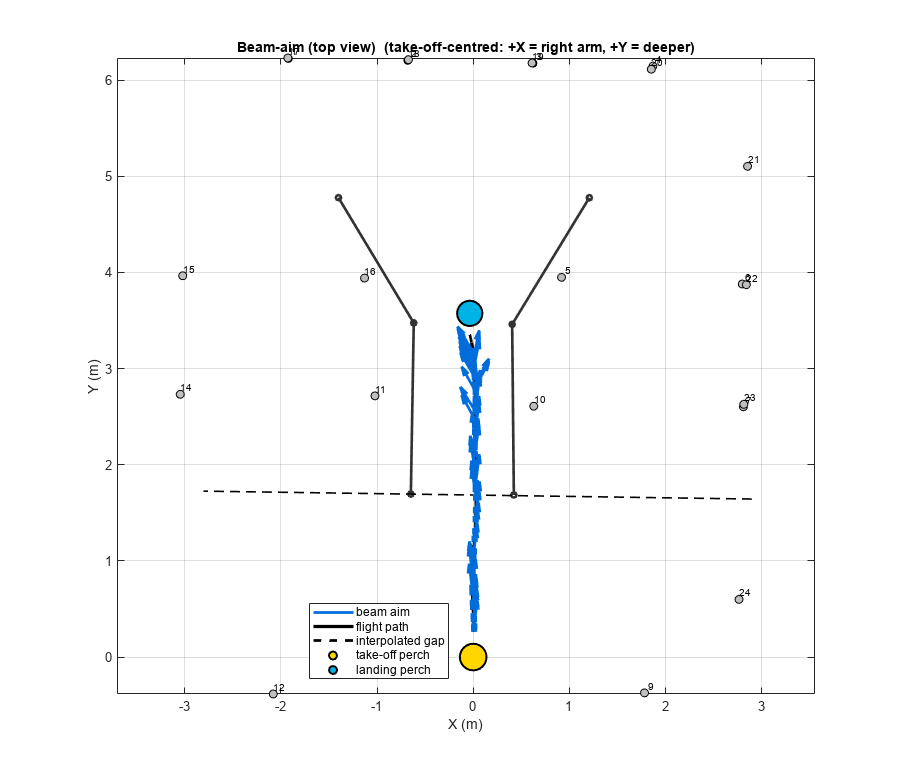

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000008_beamaim_qc.png (+ 20260708_T0000008_beamaim_qc.fig)


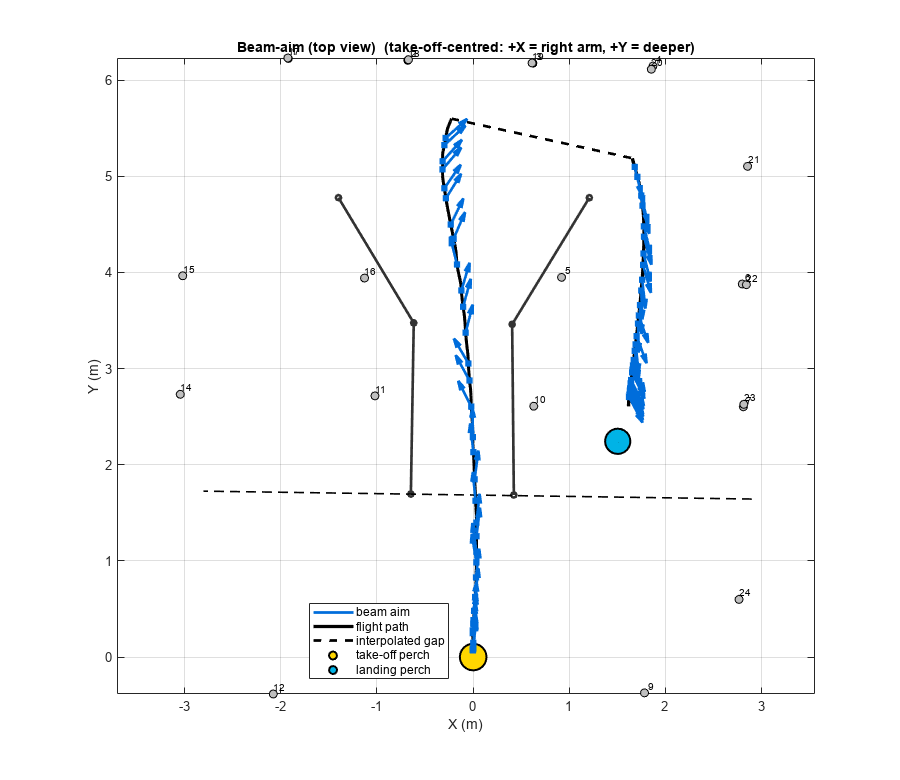

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000009_beamaim_qc.png (+ 20260708_T0000009_beamaim_qc.fig)


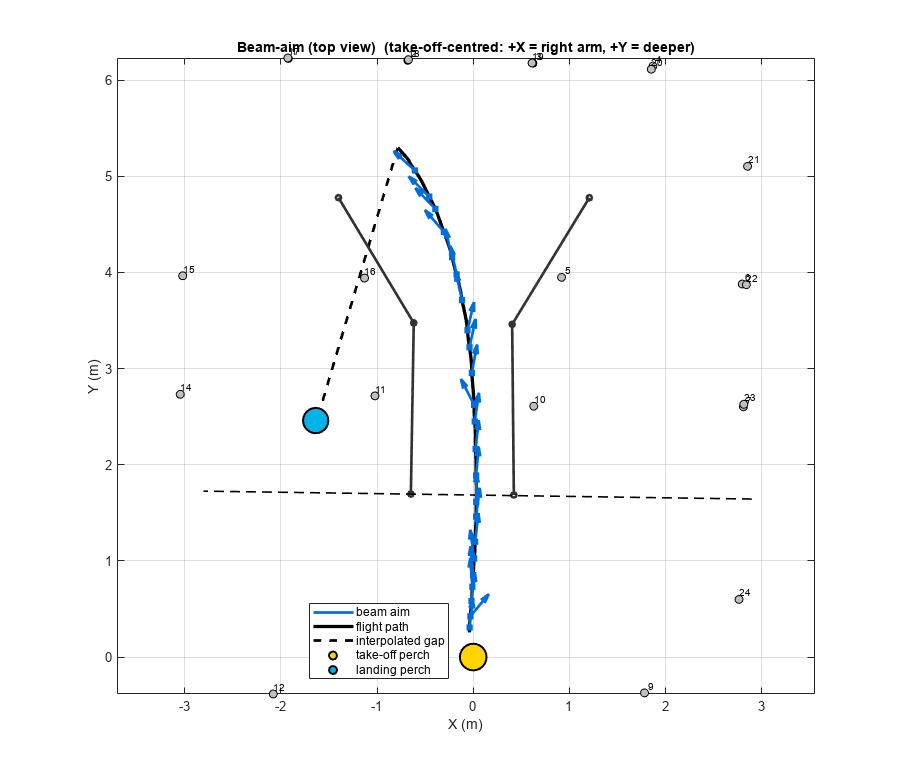

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000010_beamaim_qc.png (+ 20260708_T0000010_beamaim_qc.fig)


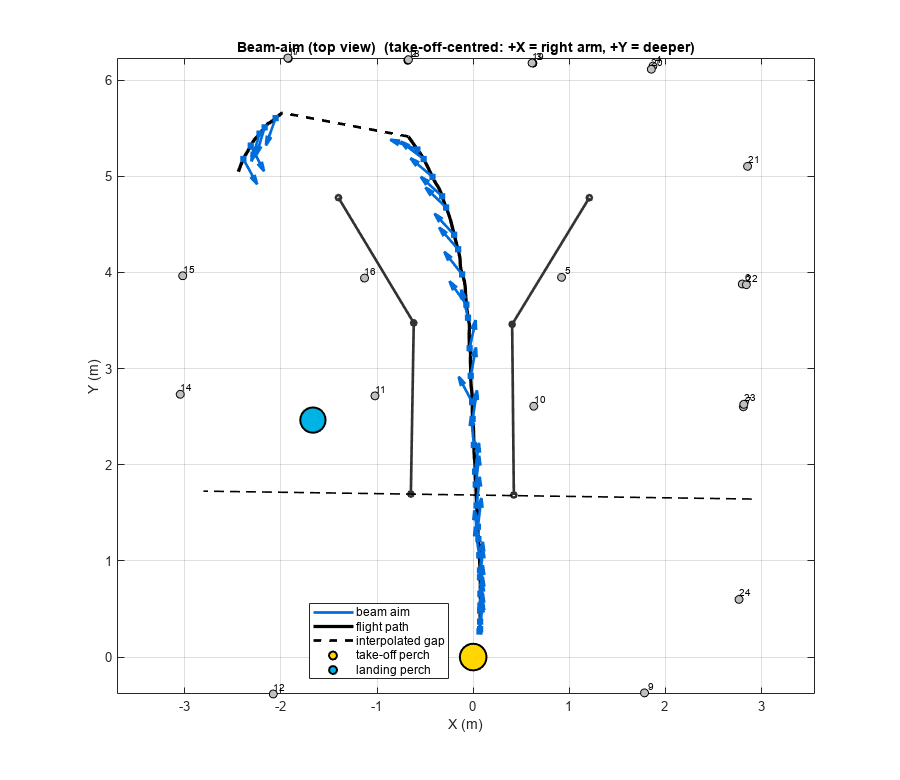

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000011_beamaim_qc.png (+ 20260708_T0000011_beamaim_qc.fig)


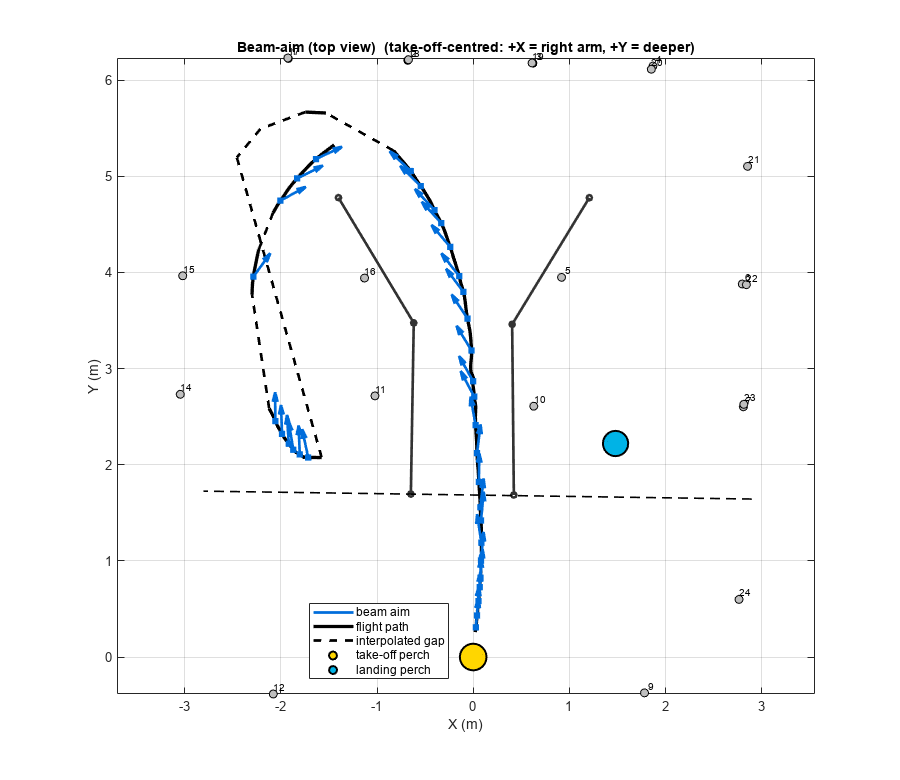

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000012_beamaim_qc.png (+ 20260708_T0000012_beamaim_qc.fig)


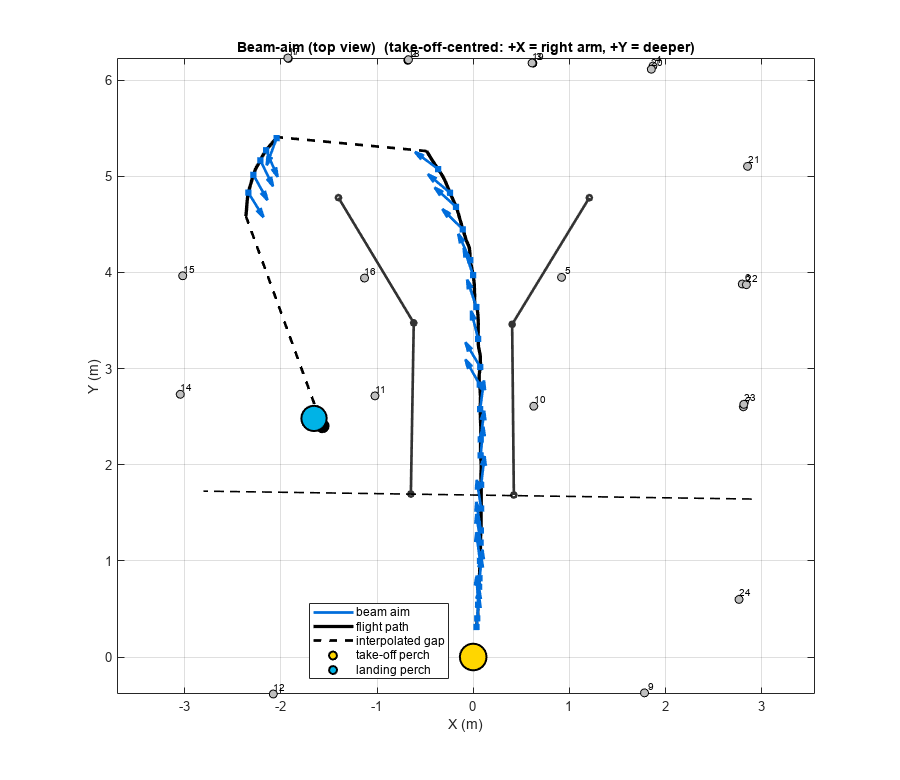

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000013_beamaim_qc.png (+ 20260708_T0000013_beamaim_qc.fig)


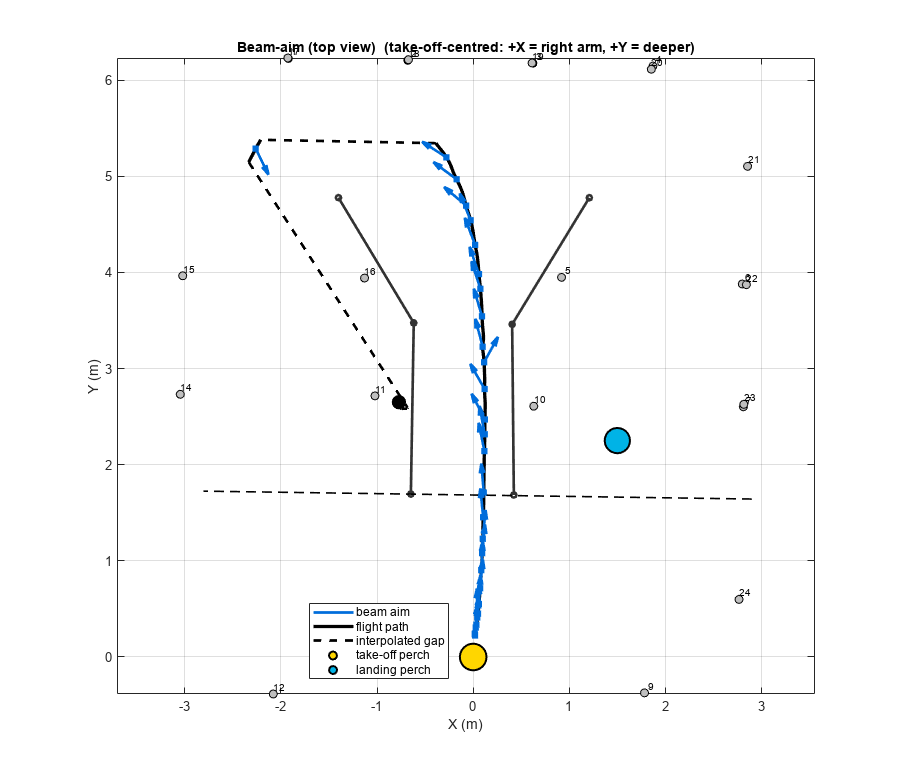

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000014_beamaim_qc.png (+ 20260708_T0000014_beamaim_qc.fig)


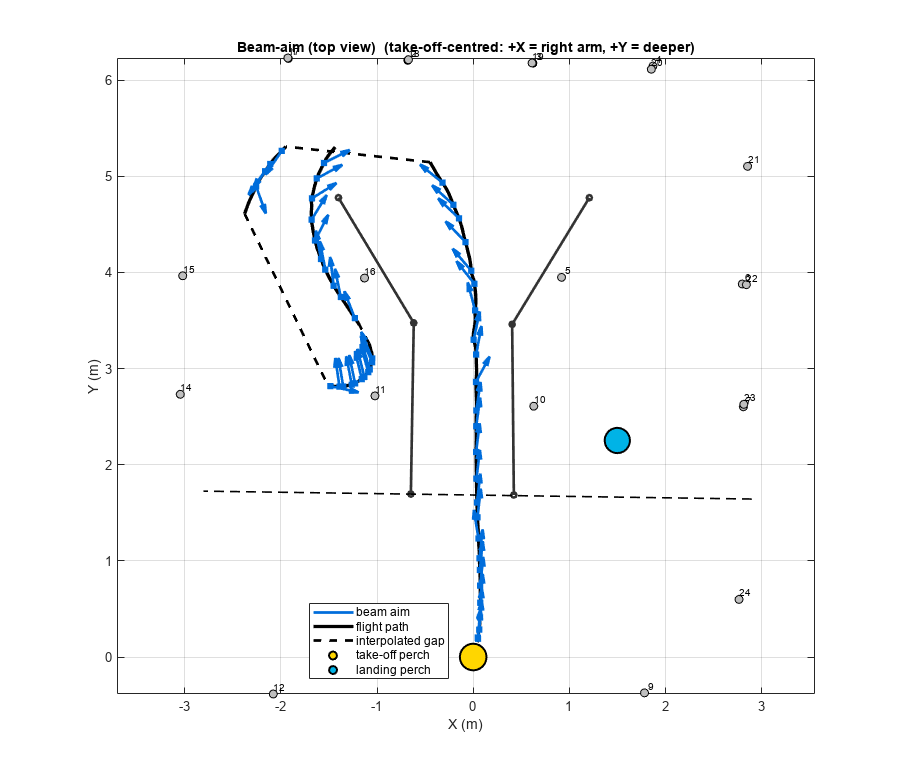

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000015_beamaim_qc.png (+ 20260708_T0000015_beamaim_qc.fig)


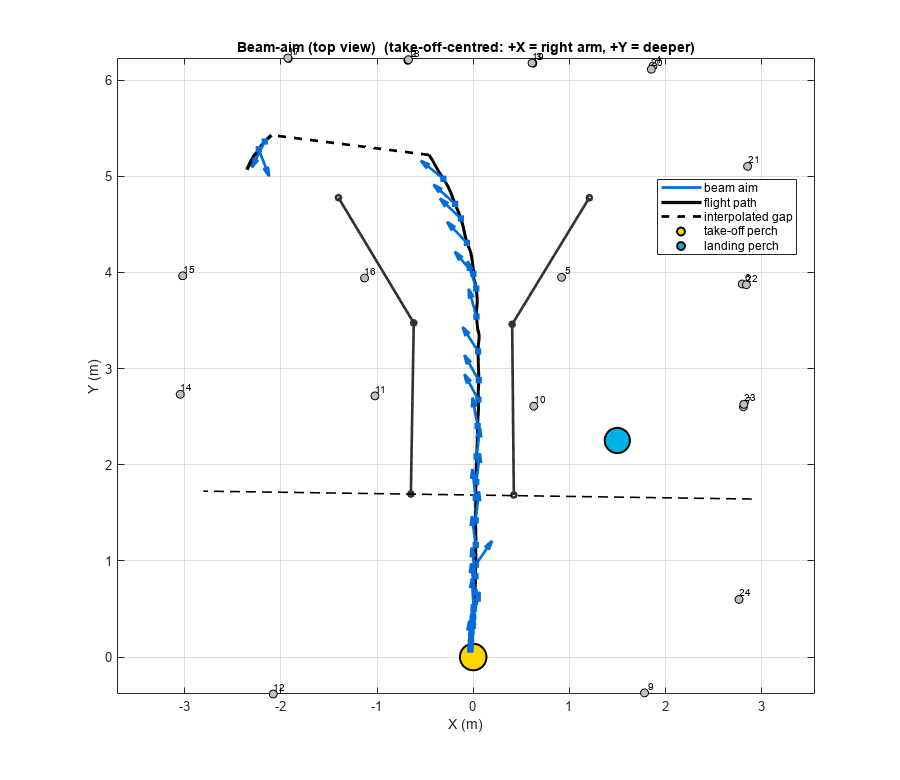

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000016_beamaim_qc.png (+ 20260708_T0000016_beamaim_qc.fig)


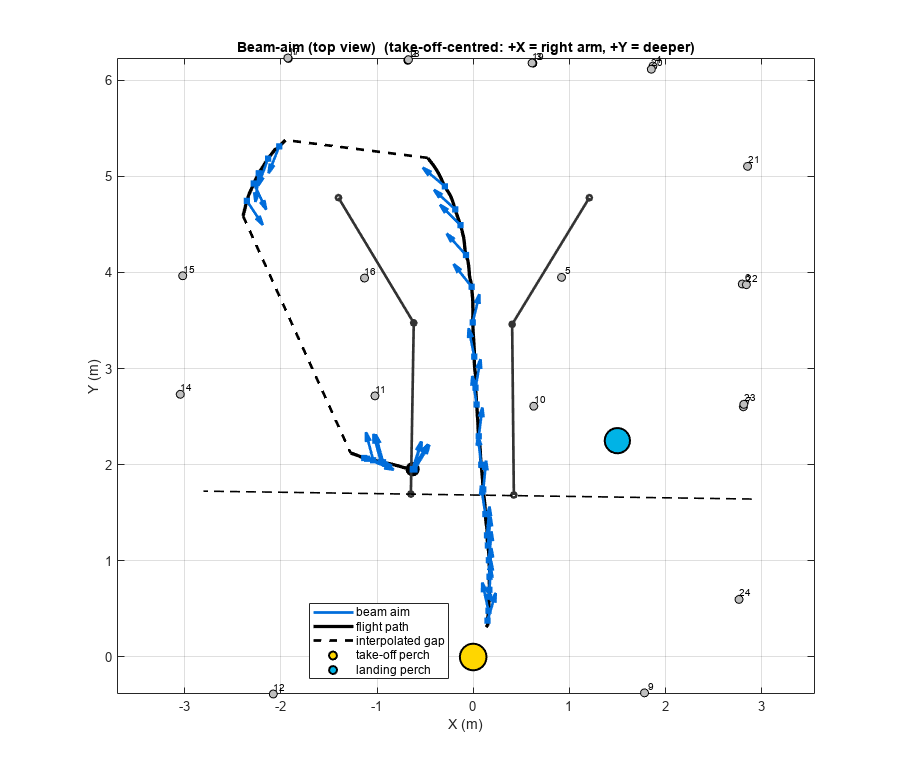

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000017_beamaim_qc.png (+ 20260708_T0000017_beamaim_qc.fig)


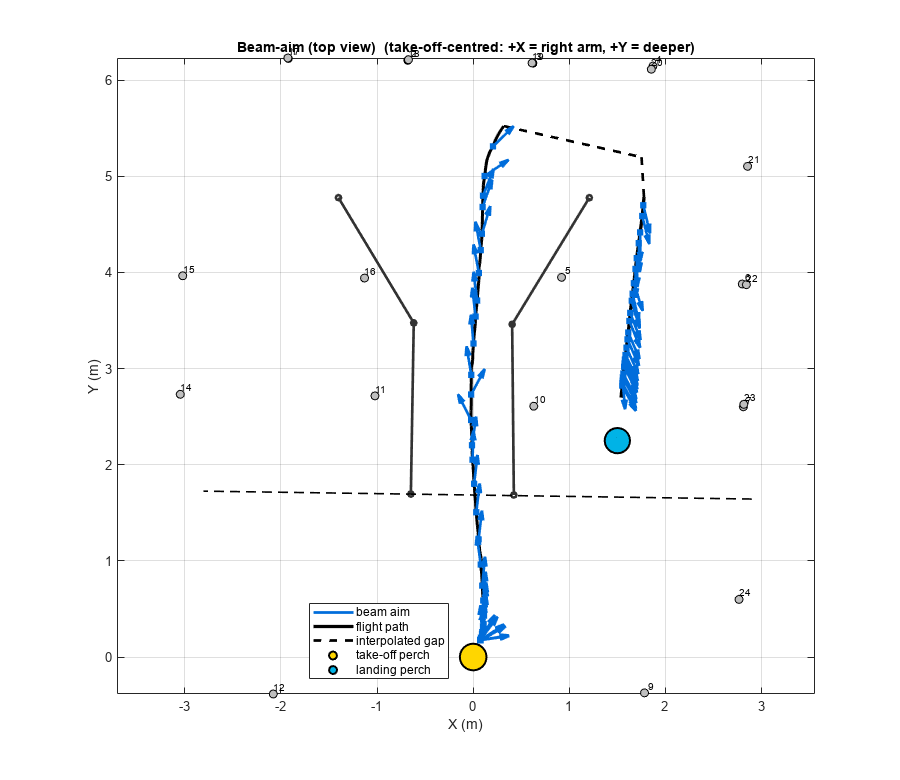

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000018_beamaim_qc.png (+ 20260708_T0000018_beamaim_qc.fig)


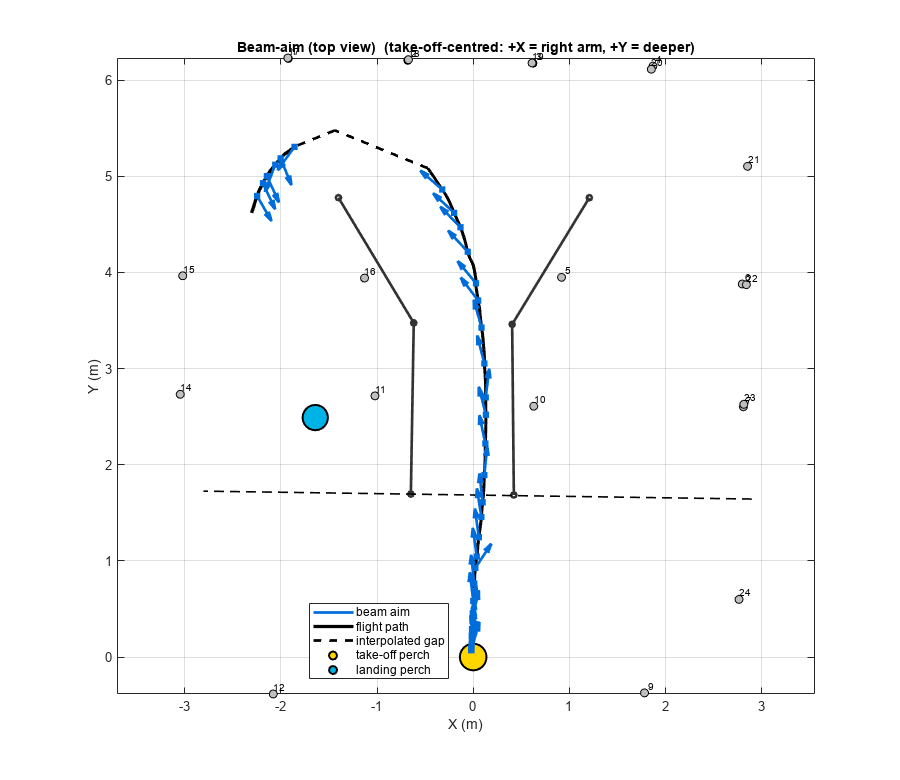

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000019_beamaim_qc.png (+ 20260708_T0000019_beamaim_qc.fig)


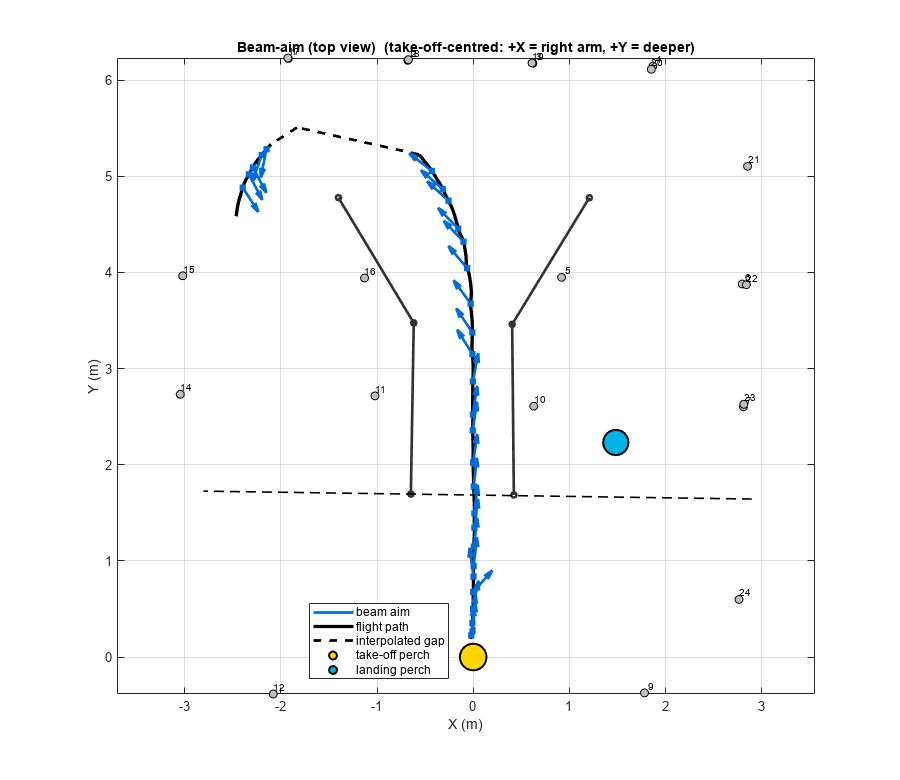

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000020_beamaim_qc.png (+ 20260708_T0000020_beamaim_qc.fig)


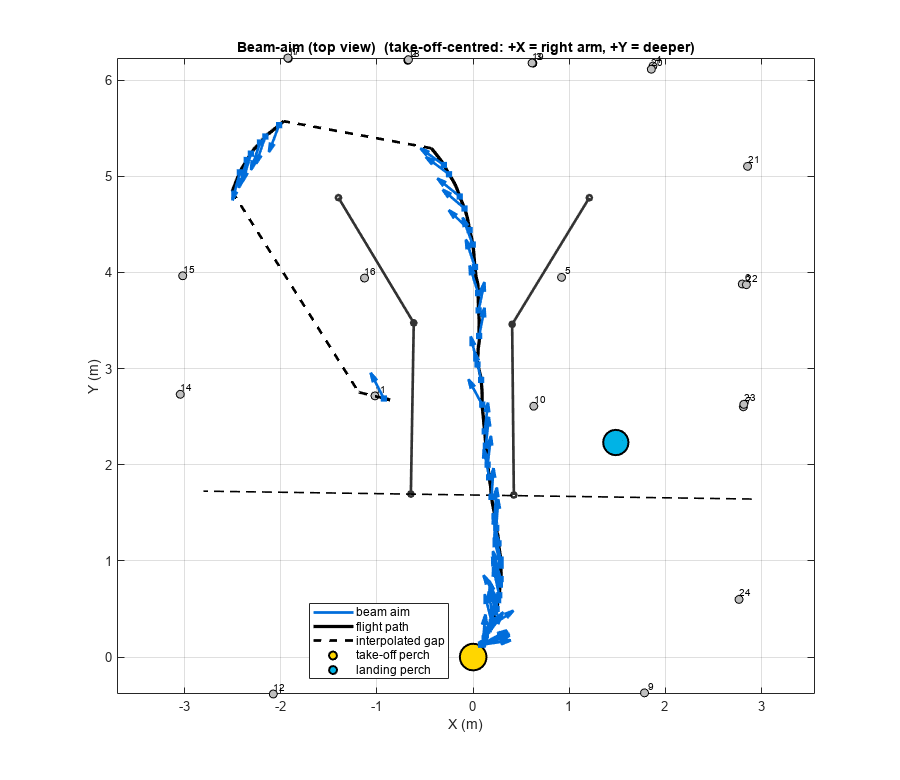

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000021_beamaim_qc.png (+ 20260708_T0000021_beamaim_qc.fig)


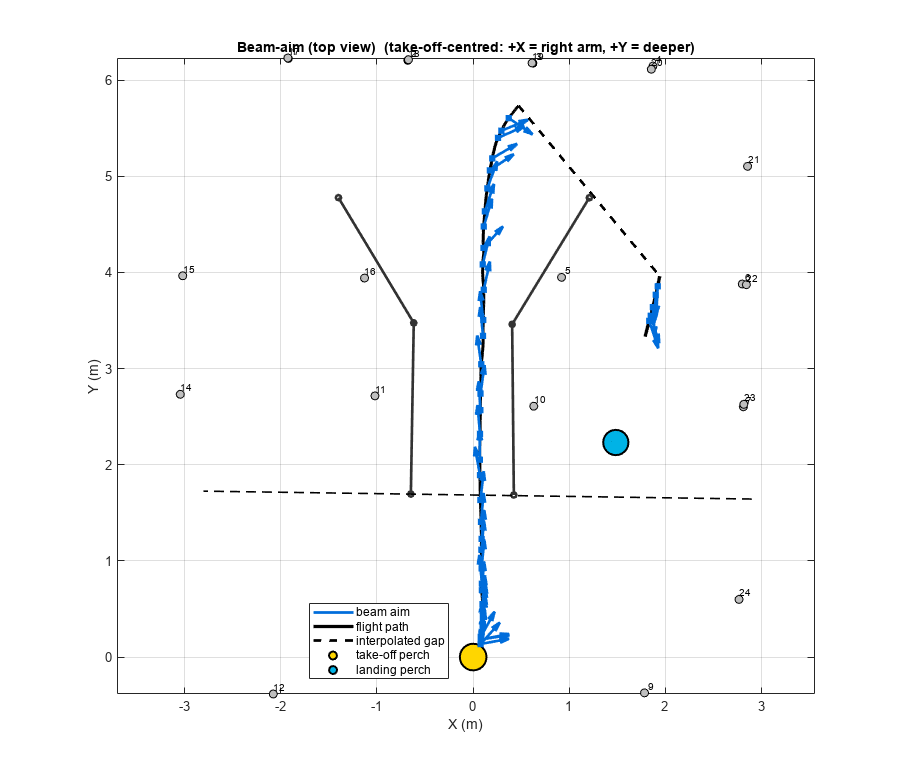

Saved QC plot Z:\Rie\Data\Beampattern_proc\batA125\plot\20260708_T0000022_beamaim_qc.png (+ 20260708_T0000022_beamaim_qc.fig)


        if make_plots
            try
                %plot_mic_zone_selection_qc(bat_pos_file, mic_pos_file);
                plot_beamaim_qc(bp_proc_file, out);
                close all;
            catch MEp
                fprintf(2, '  (QC plot warning trial %02d: %s)\n', n, MEp.message);
            end
        end

## stage 4 -- trial metrics + study tables (MOVED OUT: see trial_analysis_batch_processing.m)

        %{
        if do_stage4
            run_trial_analysis(struct( ...
                'bp_proc_file', bp_proc_file, ...
                'bat_pos_file', bat_pos_file, ...
                'out_root',     out_root_stats, ...
                'plot',         make_plots));
            if make_plots, close all; end
        end
        %}

        n_ok = n_ok + 1;
    catch ME
        fprintf(2, '  TRIAL %02d FAILED: %s\n', n, ME.message);
        failed{end+1} = sprintf('%02d', n); n_fail = n_fail + 1; %#ok<SAGROW>
    end
end

fprintf('\n==== Beam session batch done: %d OK, %d failed, %d skipped ====\n', n_ok, n_fail, n_skip);


==== Beam session batch done: 15 OK, 0 failed, 3 skipped ====


if ~isempty(failed),  fprintf('Failed:  %s\n', strjoin(failed,  ', ')); end
if ~isempty(skipped), fprintf('Skipped: %s\n', strjoin(skipped, ', ')); end

Skipped: 02, 03, 04


## ---- pooled pre-flight beam figure across the session's trials ---- (MOVED OUT)

(uses goal-relative azimuth, correct for pooling across moving perches) Now produced by trial_analysis_batch_processing.m.

%{
if do_stage4 && make_plots
    pfmat = fullfile(out_root_stats, 'preflight_calls.mat');
    if isfile(pfmat)
        M = load(pfmat);   % variable T
        try
            plot_preflight_beam(M.T, [], [], struct('tag', sprintf('%s_%s', batID, date_data), ...
                'save_dir', fullfile(out_root_stats, 'plots')));
            close all;
        catch MEp
            fprintf(2, '(pooled plot warning: %s)\n', MEp.message);
        end
    end
end
%}